A = sym([1 2 3; 0 0 0]), b = sym([7; 0])

$$A = \left(\begin{array}{ccc} 1 & 2 & 3\\ 0 & 0 & 0 \end{array}\right)$$

$$b = \left(\begin{array}{c} 7\\ 0 \end{array}\right)$$

[R, E] = rref2(A), z = E * b

$$R = \left(\begin{array}{ccc} 1 & 2 & 3\\ 0 & 0 & 0 \end{array}\right)$$

$$E = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

$$z = \left(\begin{array}{c} 7\\ 0 \end{array}\right)$$

rowv = rowspace(A)

$$rowv = \left(\begin{array}{c} 1\\ 2\\ 3 \end{array}\right)$$

nullv = null(A)

$$nullv = \left(\begin{array}{cc} -2 & -3\\ 1 & 0\\ 0 & 1 \end{array}\right)$$

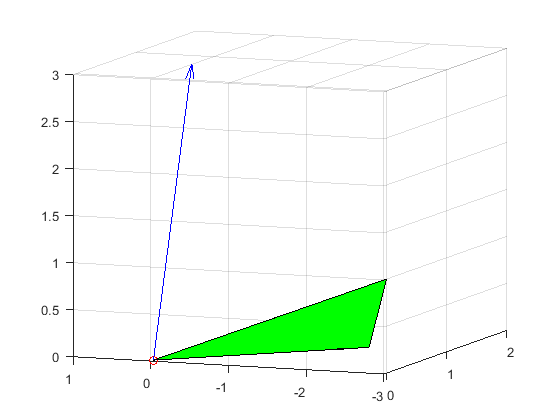

syms t;

figure
quiver3(0, 0, 0, rowv(1, 1), rowv(2, 1), rowv(3, 1), 'b')
hold on
quiver3(0, 0, 0, nullv(1, 1), nullv(2, 1), nullv(3, 1), 'k')
quiver3(0, 0, 0, nullv(1, 2), nullv(2, 2), nullv(3, 2), 'k')

patch([0 double(nullv(1, :))], [0 double(nullv(2, :))], [0 double(nullv(3, :))], 'green')
 plot3(0, 0, 0, 'ro')

A2 = A', b2 = R \ z

$$A2 = \left(\begin{array}{cc} 1 & 0\\ 2 & 0\\ 3 & 0 \end{array}\right)$$

$$b2 = \left(\begin{array}{c} 7\\ 0\\ 0 \end{array}\right)$$

[R2, E2] = rref2(A2), z2 = E2 * b2

$$R2 = \left(\begin{array}{cc} 1 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

$$E2 = \left(\begin{array}{ccc} 0 & 0 & \frac{1}{3}\\ 1 & 0 & -\frac{1}{3}\\ 0 & 1 & -\frac{2}{3} \end{array}\right)$$

$$z2 = \left(\begin{array}{c} 0\\ 7\\ 0 \end{array}\right)$$

rowv2 = rowspace(A2)

$$rowv2 = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

nullv2 = null(A2)

$$nullv2 = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

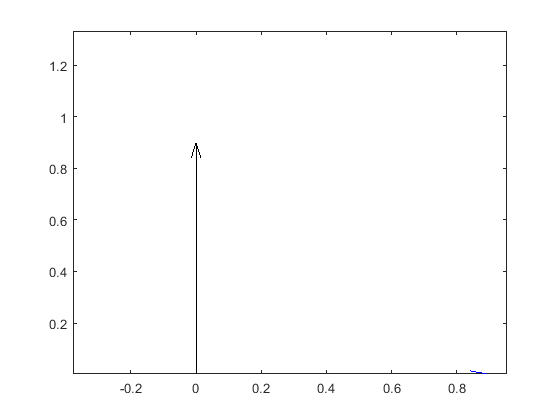

syms t;

figure
quiver(0, 0, rowv2(1, 1), rowv2(2, 1), 'b')
hold on
quiver(0, 0, nullv2(1, 1), nullv2(2, 1), 'k')

plot(0, 0, 'ro')